hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4, 3);
colisoes = zeros(4, 3);
tempos = zeros(4, 3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop sobre diferentes tamanhos de tabela hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'djb2'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));

    fprintf("string2hash(sdbm):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'sdbm'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));

    fprintf("hashstring:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função personalizada 'hashstring'
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));

    fprintf("DJB31MA:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'DJB31MA'
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18192


	Elapsed time: 0.107465



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 18283


	Elapsed time: 0.216519



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35518


	Elapsed time: 0.742236



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18365


	Elapsed time: 0.108029



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9383


	Elapsed time: 0.187955



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9610


	Elapsed time: 0.169684



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28291


	Elapsed time: 0.651659



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9721


	Elapsed time: 0.104688



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4863


	Elapsed time: 0.105089



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4888


	Elapsed time: 0.195940



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22056


	Elapsed time: 0.761522



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 5081


	Elapsed time: 0.087903



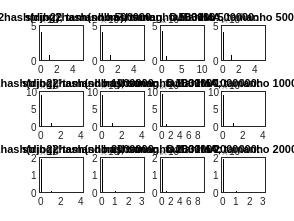


titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4*(i-1)+j);
        histogram(resultados{j, i}, 100);
        title(sprintf("%s, tamanho %d:", titles{j}, hashTableSizes(i)));
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4, 3);
colisoes = zeros(4, 3);
tempos = zeros(4, 3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop sobre diferentes tamanhos de tabela hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'djb2'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));

    fprintf("string2hash(sdbm):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'sdbm'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));

    fprintf("hashstring:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função personalizada 'hashstring'
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));

    fprintf("DJB31MA:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'DJB31MA'
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18023


	Elapsed time: 0.129476



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 18128


	Elapsed time: 0.167662



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35615


	Elapsed time: 0.723630



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18229


	Elapsed time: 0.080340



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9383


	Elapsed time: 0.099070



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9489


	Elapsed time: 0.191219



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28414


	Elapsed time: 0.796895



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9599


	Elapsed time: 0.084885



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4808


	Elapsed time: 0.132026



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4765


	Elapsed time: 0.182084



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 21983


	Elapsed time: 0.771746



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4948


	Elapsed time: 0.095434



Momentos:


	Momento de ordem 2: 2.395880e-01
	Momento de ordem 5: 1.000580e+00
	Momento de ordem 10: 1.572775e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.400320e-01
	Momento de ordem 5: 1.023080e+00
	Momento de ordem 10: 1.808218e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.381040e-01
	Momento de ordem 5: 1.339010e+01
	Momento de ordem 10: 1.014655e+05


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.405040e-01
	Momento de ordem 5: 1.038020e+00
	Momento de ordem 10: 1.535581e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.098600e-01
	Momento de ordem 5: 2.730700e-01
	Momento de ordem 10: 1.671876e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.099900e-01
	Momento de ordem 5: 2.762200e-01
	Momento de ordem 10: 1.723303e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.546440e-01
	Momento de ordem 5: 4.986700e+00
	Momento de ordem 10: 2.912091e+04


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.100940e-01
	Momento de ordem 5: 2.774800e-01
	Momento de ordem 10: 1.717421e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.245500e-02
	Momento de ordem 5: 8.937500e-02
	Momento de ordem 10: 2.256165e+00


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.243800e-02
	Momento de ordem 5: 8.934500e-02
	Momento de ordem 10: 2.331448e+00


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 6.974800e-02
	Momento de ordem 5: 1.511375e+00
	Momento de ordem 10: 6.302961e+03


------------------------------------------------------------------------------------------


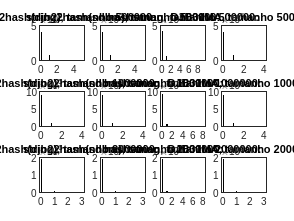

Momentos:


	Momento de ordem 2: 5.254000e-02
	Momento de ordem 5: 9.140000e-02
	Momento de ordem 10: 2.579500e+00


------------------------------------------------------------------------------------------



titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4*(i-1)+j);
        histogram(resultados{j, i}, 100);
        title(sprintf("%s, tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i};
        [contagem, valores] = groupcounts(valores);
        
        % Loop para calcular momentos de ordem 2, 5 e 10
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n)*(contagem(x)/hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d: %d\n", n, En);
        end
        
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N,i_min,i_max,chars);

resultados = cell(4,3);
colisoes = zeros(4,3);
tempos=zeros(4,3);
codes1 = zeros(4,N);
codes2 = zeros(4,N);
codes3 = zeros(4,N);

% Loop para iterar sobre os tamanhos da tabela hash
for i= 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    
    % Loop para iterar sobre as strings geradas
    for j= 1:N
        code = mod(string2hash(strings{j},'djb2'),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1,j) = code;
        elseif i == 2
            codes2(1,j) = code;
        else
            codes3(1,j) = code;
        end
    end
    resultados{1,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(1,i) = numColisoes;
    tempos(1,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(1,i));

    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    for j= 1:N
        code = mod(string2hash(strings{j},'sdbm'),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(2,j) = code;
        elseif i == 2
            codes2(2,j) = code;
        else
            codes3(2,j) = code;
        end
    end
    resultados{2,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(2,i) = numColisoes;
    tempos(2,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(2,i));

    fprintf("hashstring:\n");
    tic;
    hash_table=zeros(hashTableSizes(i),1);
    for j= 1:N
        code = hashstring(strings{j},hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(3,j) = code;
        elseif i == 2
            codes2(3,j) = code;
        else
            codes3(3,j) = code;
        end
    end
    resultados{3,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(3,i) = numColisoes;
    tempos(3,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(3,i));

    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    for j= 1:N
        code = mod(DJB31MA(strings{j},13),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(4,j) = code;
        elseif i == 2
            codes2(4,j) = code;
        else
            codes3(4,j) = code;
        end
    end
    resultados{4,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(4,i) = numColisoes;
    tempos(4,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(4,i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18197


	Elapsed time: 0.124528



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 17990


	Elapsed time: 0.199134



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35229


	Elapsed time: 0.926900



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18185


	Elapsed time: 0.111962



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9390


	Elapsed time: 0.136902



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9486


	Elapsed time: 0.220432



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 27954


	Elapsed time: 0.772818



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9555


	Elapsed time: 0.107016



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4802


	Elapsed time: 0.172287



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4847


	Elapsed time: 0.211131



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 21775


	Elapsed time: 0.715352



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4916


	Elapsed time: 0.095858



Momentos:


	Momento de ordem 2: 2.399880e-01
	Momento de ordem 5: 1.019660e+00
	Momento de ordem 10: 2.748855e+02


Número de colisões: 18197


Numero máximo de atribuiçoes numa posição: 6


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.395000e-01
	Momento de ordem 5: 9.920000e-01
	Momento de ordem 10: 1.443177e+02


Número de colisões: 17990


Numero máximo de atribuiçoes numa posição: 5


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.343200e-01
	Momento de ordem 5: 1.280282e+01
	Momento de ordem 10: 1.121315e+05


Número de colisões: 35229


Numero máximo de atribuiçoes numa posição: 9


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.400240e-01
	Momento de ordem 5: 1.008320e+00
	Momento de ordem 10: 1.506586e+02


Número de colisões: 18185


Numero máximo de atribuiçoes numa posição: 5


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.746850e-02
	Momento de ordem 5: 8.619687e-03
	Momento de ordem 10: 2.082259e-02


Número de colisões: 9390


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.748850e-02
	Momento de ordem 5: 8.563437e-03
	Momento de ordem 10: 1.620982e-02


Número de colisões: 9486


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.818250e-02
	Momento de ordem 5: 1.472591e-01
	Momento de ordem 10: 3.465177e+01


Número de colisões: 27954


Numero máximo de atribuiçoes numa posição: 9


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.751250e-02
	Momento de ordem 5: 8.650625e-03
	Momento de ordem 10: 1.674974e-02


Número de colisões: 9555


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.830556e-03
	Momento de ordem 5: 3.755761e-04
	Momento de ordem 10: 6.077537e-05


Número de colisões: 4802


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.830000e-03
	Momento de ordem 5: 3.677984e-04
	Momento de ordem 10: 3.691612e-05


Número de colisões: 4847


Numero máximo de atribuiçoes numa posição: 3


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.684222e-03
	Momento de ordem 5: 6.170453e-03
	Momento de ordem 10: 1.567378e-01


Número de colisões: 21775


Numero máximo de atribuiçoes numa posição: 9


------------------------------------------------------------------------------------------


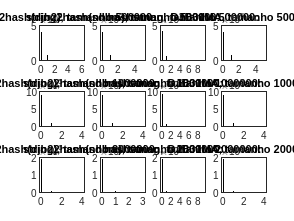

Momentos:


	Momento de ordem 2: 5.835111e-03
	Momento de ordem 5: 3.739095e-04
	Momento de ordem 10: 4.851117e-05


Número de colisões: 4916


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles={'string2hash(djb2)','string2hash(sdbm)','hashstring','DJB31MA'};
momentos = zeros(3,10);

% Loop para plotar histogramas e calcular momentos
for i= 1:3
    for j= 1:4
        subplot(3,4,4*(i-1)+j);
        histogram(resultados{j,i},100);
        title(sprintf("%s, tamanho %d:",titles{j},hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j,i}/i;
        [contagem,valores] = groupcounts(valores);
        for n= [2,5,10]       
            En = 0;
            for x= 1:length(valores)
                En = En + ((valores(x)^n)*(contagem(x)/hashTableSizes(i)));
            end
            momentos(i,n)=En;
            fprintf("\tMomento de ordem %d: %d\n",n,En);
        end
        
        fprintf("\n");
        fprintf("Número de colisões: %d\n",colisoes(j,i));
        fprintf("Numero máximo de atribuiçoes numa posição: %d\n",max(resultados{j,i}));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4,3);
colisoes = zeros(4,3);
tempos = zeros(4,3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop para iterar sobre os tamanhos da tabela hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para iterar sobre as strings geradas
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));

    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));

    fprintf("hashstring:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));

    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18066


	Elapsed time: 0.091729



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 18390


	Elapsed time: 0.171595



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35399


	Elapsed time: 0.925319



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 17989


	Elapsed time: 0.079302



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9429


	Elapsed time: 0.111202



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9585


	Elapsed time: 0.164768



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28150


	Elapsed time: 0.752728



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9418


	Elapsed time: 0.093104



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4788


	Elapsed time: 0.223190



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4833


	Elapsed time: 0.183173



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 21778


	Elapsed time: 0.698972



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4874


	Elapsed time: 0.096677



Momentos:


	Momento de ordem 2: 2.398760e-01
	Momento de ordem 5: 1.013240e+00
	Momento de ordem 10: 1.576213e+02


Número de colisões: 18066


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.091729

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.404320e-01
	Momento de ordem 5: 1.008440e+00
	Momento de ordem 10: 1.283061e+02


Número de colisões: 18390


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.171595

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.367040e-01
	Momento de ordem 5: 1.328444e+01
	Momento de ordem 10: 1.207275e+05


Número de colisões: 35399


Numero máximo de atribuiçoes numa posição: 10


Tempo de execução: 0.925319

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.398840e-01
	Momento de ordem 5: 1.035020e+00
	Momento de ordem 10: 2.092682e+02


Número de colisões: 17989


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.079302

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.748500e-02
	Momento de ordem 5: 8.651562e-03
	Momento de ordem 10: 1.873086e-02


Número de colisões: 9429


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.111202

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.751400e-02
	Momento de ordem 5: 8.615938e-03
	Momento de ordem 10: 1.631539e-02


Número de colisões: 9585


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.164768

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.843200e-02
	Momento de ordem 5: 1.537934e-01
	Momento de ordem 10: 3.997776e+01


Número de colisões: 28150


Numero máximo de atribuiçoes numa posição: 10


Tempo de execução: 0.752728

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.748350e-02
	Momento de ordem 5: 8.670312e-03
	Momento de ordem 10: 1.969121e-02


Número de colisões: 9418


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.093104

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.829889e-03
	Momento de ordem 5: 3.763169e-04
	Momento de ordem 10: 6.860233e-05


Número de colisões: 4788


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.223190

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.830333e-03
	Momento de ordem 5: 3.709465e-04
	Momento de ordem 10: 4.766504e-05


Número de colisões: 4833


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.183173

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.708333e-03
	Momento de ordem 5: 6.210021e-03
	Momento de ordem 10: 1.342829e-01


Número de colisões: 21778


Numero máximo de atribuiçoes numa posição: 8


Tempo de execução: 0.698972

------------------------------------------------------------------------------------------


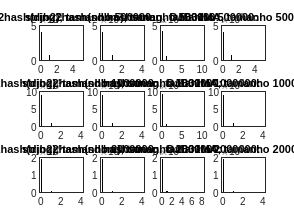

Momentos:


	Momento de ordem 2: 5.833556e-03
	Momento de ordem 5: 3.753909e-04
	Momento de ordem 10: 5.816495e-05


Número de colisões: 4874


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.096677

------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4 * (i - 1) + j);
        histogram(resultados{j, i}, 100);
        title(sprintf("%s, tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i} / i;
        [contagem, valores] = groupcounts(valores);
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n) * (contagem(x) / hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d: %d\n", n, En);
        end

        fprintf("\n");
        fprintf("Número de colisões: %d\n", colisoes(j, i));
        fprintf("Numero máximo de atribuiçoes numa posição: %d\n", max(resultados{j, i}));
        fprintf("Tempo de execução: %f", tempos(j, i));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end